noisy_img = im2double(imread("noisy.jpg"))

noisy_img =     0.1176         0    0.1059    0.1176    0.1216         0    0.0157    0.1137    0.1059    0.0627    0.0118    0.0157    1.0000    0.0235    0.1176    0.0078    0.0196    0.1059         0    0.0039    0.0588    0.0314    0.0471    0.0549    1.0000    0.0549    0.0510         0    0.0863    0.9725    0.0196    0.0392    0.0863    0.0863    0.0353    0.0784    0.0902    0.2039    0.3490    0.2706         0    0.2745    0.2353    0.1569    0.0902    0.0784    0.0588    0.0863    0.1020    0.1490
    0.9608    0.1294    0.0588    0.0353    0.1686    0.1529    0.1137    0.0902    0.0549    0.0941    1.0000    0.0706    0.1176    0.0078         0    0.0706    0.0118    0.0471    0.0863    0.0941         0    0.0549    0.1373         0         0    0.0353    0.1020    0.0784         0    0.0157    1.0000    0.0510         0    0.2471    0.3098    0.2784    0.4235    1.0000    0.8941    0.5882    0.5098    1.0000    0.4510         0    1.0000    0.3647         0    0.2902    0.4

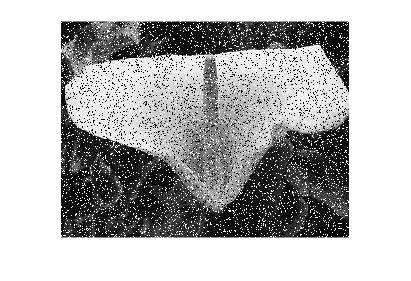

imshow("noisy.jpg")

first_pass = medfilt2(noisy_img)

first_pass =          0    0.0588    0.0353    0.0588    0.0353    0.0157    0.0157    0.0549    0.0627    0.0549    0.0157    0.0157    0.0157    0.0078    0.0078    0.0078    0.0118    0.0118    0.0039         0    0.0039    0.0314    0.0314         0         0    0.0353    0.0353         0         0    0.0157    0.0196    0.0196    0.0392    0.0353    0.0784    0.0784    0.0902    0.2039    0.2706    0.2706    0.2706    0.2353    0.1569    0.0902    0.0784    0.0588    0.0588    0.0588    0.1020    0.1020
    0.1020    0.1059    0.1059    0.1059    0.1176    0.1137    0.0902    0.0902    0.0902    0.0941    0.0627    0.0863    0.0706    0.0863    0.0235    0.0196    0.0275    0.0471    0.0667    0.0588    0.0314    0.0314    0.0471    0.0549    0.0549    0.0510    0.0431    0.0510    0.0431    0.0627    0.0510    0.0863    0.0863    0.2471    0.2784    0.3098    0.4235    0.5294    0.5882    0.5765    0.5647    0.5098    0.4510    0.4510    0.3647    0.3647    0.2902    0.2902    0.

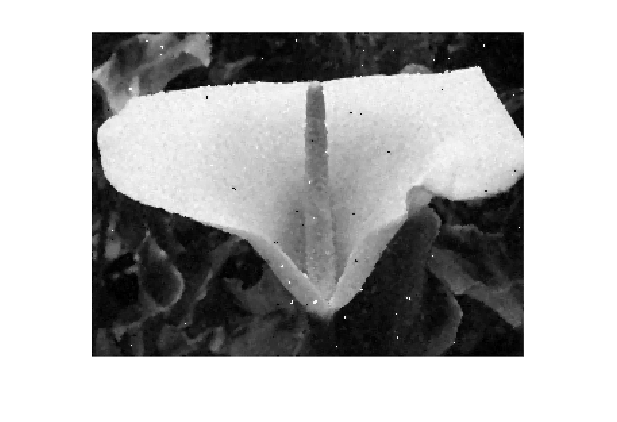

imshow(im2uint8(med_filtered_img))

second_pass = medfilt2(med_filtered_img)

second_pass =          0    0.0353    0.0588    0.0353    0.0353    0.0157    0.0157    0.0549    0.0549    0.0549    0.0157    0.0157    0.0157    0.0078    0.0078    0.0078    0.0118    0.0118    0.0039    0.0039    0.0039    0.0314    0.0314         0         0    0.0353    0.0353         0         0    0.0157    0.0196    0.0196    0.0353    0.0392    0.0784    0.0784    0.0902    0.2039    0.2706    0.2706    0.2706    0.2353    0.1569    0.0902    0.0784    0.0588    0.0588    0.0588    0.1020    0.1020
    0.0588    0.0863    0.0863    0.0863    0.0902    0.0902    0.0902    0.0902    0.0784    0.0706    0.0706    0.0706    0.0706    0.0471    0.0235    0.0235    0.0275    0.0471    0.0471    0.0471    0.0314    0.0314    0.0353    0.0353    0.0353    0.0353    0.0431    0.0431    0.0431    0.0431    0.0627    0.0863    0.0863    0.2314    0.2784    0.3098    0.4235    0.5294    0.5451    0.5647    0.5451    0.5098    0.4510    0.4510    0.3647    0.3647    0.2902    0.2902    0

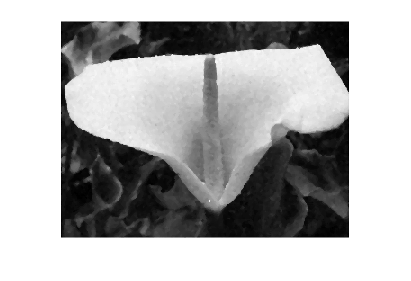

imshow(im2uint8(second_pass))

noise_free = im2double(imread("original.jpg"))

noise_free =     0.0902    0.0824    0.0863    0.1020    0.1176    0.1255    0.1176    0.1059    0.0863    0.0627    0.0431    0.0392    0.0510    0.0627    0.0549    0.0431    0.0510    0.0510    0.0549    0.0627    0.0667    0.0627    0.0549    0.0471    0.0588    0.0392    0.0314    0.0471    0.0471    0.0275    0.0235    0.0392    0.0667    0.0784    0.0471    0.0235    0.1137    0.2627    0.3059    0.2549    0.2745    0.2510    0.2078    0.1569    0.1098    0.0784    0.0706    0.0706    0.1020    0.1882
    0.0941    0.0863    0.0863    0.0980    0.1137    0.1137    0.1020    0.0902    0.0824    0.0627    0.0431    0.0431    0.0549    0.0667    0.0588    0.0510    0.0549    0.0510    0.0471    0.0471    0.0510    0.0510    0.0471    0.0431    0.0353    0.0314    0.0392    0.0510    0.0431    0.0275    0.0392    0.0706    0.1843    0.2706    0.3216    0.3333    0.4000    0.5176    0.5725    0.5529    0.5059    0.4863    0.4510    0.4078    0.3647    0.3294    0.3137    0.3098    0.

original_psnr = num2str(psnr(noisy_img, noise_free), '%05.2f')

original_psnr = '11.33'

first_pass_psnr = num2str(psnr(first_pass, noise_free), '%05.2f')

first_pass_psnr = '27.38'

second_pass_psnr = num2str(psnr(second_pass, noise_free), '%05.2f')

second_pass_psnr = '29.65'